# The logic of logit

Testing the efficacy of variable transformation for supposedly efficient sampling.

clear
close all
clc

## Change of random variable and pdf

Suppose $X\sim{p_x(x)}$ and $Y=\phi(X)$. What is $p_y(y)$? Well,


$$P(Y\in{S})=\int_S{p_y(y')dy'=P(X\in{\phi^{-1}(S)})=\int_{\phi^{-1}(S)}p_x(x')dx'=\int_Sp_x(\phi^{-1}y')\frac{d\phi^{-1}}{dy}(y')dy',$$


and since this holds for arbitrary $S$ it follows that


$$p_y = p_x(\phi^{-1})\frac{d\phi^{-1}}{dy}.$$


For example, the logit transformation $Y=\phi(X)=\ln(X) - \ln(1 - X)$ has the expit inverse

$X = \phi^{-1}(Y) = \frac{\exp(Y)}{1 + \exp(Y)}$ and $\frac{d\phi^{-1}}{dy} = \frac{e^y}{(1 + e^y)^2}$, and therefore

$p_y=p_x\frac{e^y}{(1 + e^y)^2}$.

## The uniform pdf over (0,1)

The idea is to help the sampler by avoiding likelihood "cliffs" at the ends of the finite support. I'm not sure why these cliffs are so bad, but we can avoid them with the logit transformation. If $X\sim{U(0,1)$ and $Y=\ln(X) - \ln(1 - x)$ then


$$p_x(x)=\begin{cases}1&x\in{(0,1)}\\0&\text{otherwise}\end{cases}$$


has finite support and likelihood cliffs, but

$p_y(y) = \frac{e^y}{(1 + e^y)^2}$ or $\ln{p_y} = y - 2\ln(1 + \exp(y))$

have infinite support and decays gradually. Let's see how they work with `mhsample`.

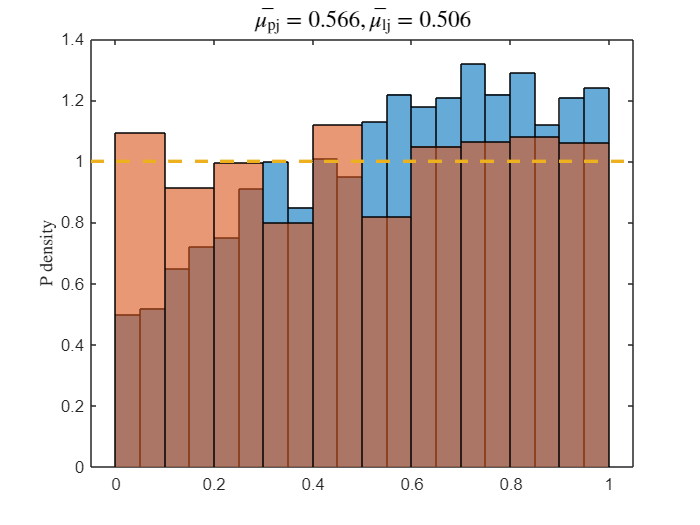

clear
clc
rng default % for reproducibility
nsamples = 2000;

logit = @(x)log(x) - log(1 - x);
expit = @(x)exp(x)./(1 + exp(x));

%% The plain jane U(0,1)
h = 0.2;
lnprob = @(x)log(double((x>=0)&(x<=1)));
prop = @(x)x + 2*h*rand() - h;

[x_pj, ar_pj] = mhsample(0.5,nsamples,logpdf=lnprob,proprnd=prop,symmetric=true);
mubar_pj = mean(x_pj);
sigbar_pj = std(x_pj);

%% The logit transformed variable
h = 4.0;
lnprob = @(y)y - 2*log(1 + exp(y));
prop = @(x)x + 2*h*rand() - h;

[y_lj, a_lj] = mhsample(0.0,nsamples,logpdf=lnprob,proprnd=prop,symmetric=true);
x_lj = expit(y_lj);

mubar_lj = mean(x_lj);
sigbar_lj = std(x_lj);

%% Compare histograms
[~,~,hh] = ngraf.nhists(x_pj,x_lj);

hline(1.0,'--')
title(sprintf("$\\bar{\\mu_\\mathrm{pj}}=%0.3f, \\bar{\\mu_\\mathrm{lj}}=%0.3f$",...
mubar_pj,mubar_lj))

### Conclusion

Inconclusive. The good news is the derived logit transformation works as expected. But it's not clear if it works any better than the plain jane uniform. It clearly depends on the proposal, like MH always does, and maybe depends on sample size. Also, I didn't do a throrough analysis of the goodness of the samples; just looked at the histograms and compared the sample means. With enough samples both methods do fine. With low sample count *maybe* the logit does better, or maybe it's an illusion or a coincidence.

## The uniform pdf over [a,b]